# **batch_run_pca_temporal**

run PCA on segmented SPA EEG data, implementing ERP appropriate PCA

author: Gerardo Parra, last updated: 2023-02-21

% eeglab; 
clear

## inputs

### loading data

task      = get_task('tss'); 
path.tag  = '_25hzLP_32hzNF';
path.eeg  = fullfile( 'X:','Groups','SPA','01_Data_Raw_Summary_Processed',  ...
                       'EEG','Participant_Data','03_Processed_Data','01_In_Progress' );
path.task = fullfile( path.eeg,task.path );
path.grps = fullfile( path.eeg,'01_Subject_Info_For_Processing', ...
                      'Group_Assignments.mat' );
group     = struct('name',{'TD','ASD','SPD'});

### processing params

P.chan.incl = 1:129; %[load_1020_chans() 29 35 110 111]; %load_1020_chans(); %
P.chan.excl_1020 = [9 17 22 33 45 58 70 75 83 96 108];
P.chan.excl_all  = [1 125 8 14 126 127 21 25 32 128 38   ...
                    43 48 44 49 56 57 63 64 68 69 73 74  ...
                    81 82 88 89 94 95 99 100 107 113 114 ...
                    120 119 121];
P.chan.excl = [P.chan.excl_all]; %[P.chan.excl_1020]
P.chan.pca  = setdiff(P.chan.incl,P.chan.excl); % channels to run PCA on
P.chan.plot = [36];       % channels to base plots on
P.t.win     = [-50 800];  % time window (ms) to use in PCA, [] to use all
P.t.rsamp   = 10;         % factor to resample time series by
P.pca.by_group = false;     % 1 = run separate PCAs by group, 0 = single PCA
P.plot_facScr  = false;

## load data

[DATA,FPI,P.t.times,P.t.seg_win,P.t.Fs] = load_eeg_into_struct(path);

### create observation matrices

EEG = struct('data',[],'mean',[],'n',[]);
if P.pca.by_group
    n.group = max([DATA.group]);
    for i_g = 1:n.group
        % create 4d matrix: channels x samples x conditions x subjects
        EEG(i_g).ids = find([DATA.group]==i_g);
        A = cat(4,DATA(EEG(i_g).ids).eeg);
        EEG(i_g).mean = squeeze(mean(A,4));
        EEG(i_g).n = size(A,4); EEG(i_g).group = group.name{i_g};
        % prep for pca: samples x channels x subjects x conditions
        EEG(i_g).data = permute(A,[2 1 4 3]); clear A
    end
else
    % create 4d matrix: channels x samples x conditions x subjects
    A = cat(4,DATA.eeg); EEG.mean = squeeze(mean(A,4)); EEG.n = size(A,4);
    EEG.ids = 1:EEG.n;
    % prep for pca: samples x channels x subjects x conditions
    EEG.data = permute(A,[2 1 4 3]); EEG.group = 'Grand'; clear A
end
for i_g = 1:length(group), group(i_g).ids = find([DATA.group]==i_g); end
n.group = size(EEG,2); n.chan = size(EEG(1).mean,1);
n.samp  = size(EEG(1).mean,2); n.cond = size(EEG(1).mean,3);

## run pca

### update PCA params

if    isempty(P.t.win), P.t.ind = 1:n.samp;
else, P.t.ind = get_time_win_idxs(P.t.win,P.t.seg_win*1000,P.t.Fs);
end
P.t.n = length(P.t.ind); P.t.plot = downsample(P.t.times(P.t.ind)*1000,P.t.rsamp);
n.rsamp = ceil(P.t.n/P.t.rsamp);
P.chan.n = length(P.chan.pca); P.chan.plot_i = P.chan.pca==P.chan.plot;
P.chan.locs = FPI.net_vstruct(P.chan.pca);

### temporal pca

adapted from Scharf et al 2022

for i_g = 1:n.group
    % get matrix: observations x samples
    A = EEG(i_g).data(:,P.chan.pca,:,:);
    A = reshape(A,[n.samp P.chan.n*EEG(i_g).n*n.cond])';
    % get selected time window
    A = A(:,P.t.ind);
    % resample
    if P.t.rsamp > 1
        A = downsample(A',P.t.rsamp)';
    end
    % EKC
    [EKC.nF,EKC.L,EKC.refs] = myEKC(corr(A),size(A,1)); 
    EEG(i_g).ekc = EKC; clear EKC
    % run PCA
    EEG(i_g).pca = ep_doPCA( 'asis', 'Geomin', 0.01, 'SVD', 'COV',  ...
                             EEG(i_g).ekc.nF, A, 'C');
end

### resort factor scores into individuals/groups

for i_g = 1:n.group    
    % reshape score: subjects x chans x conds x factor
    dims = [EEG(i_g).ekc.nF P.chan.n EEG(i_g).n n.cond];
    score = EEG(i_g).pca.FacScr; score = reshape(score',dims);
    EEG(i_g).pca.FacScrPerm = permute(score,[3 2 4 1]); clear score
end

### reconstruct data

%% TODO: SAVE INDIVIDUAL RECONSTRUCTIONS AS MAT FILES
for i_g = 1:n.group
    nF = EEG(i_g).pca.numFacs;
    % reconstruct timeseries for each factor
    for i_f = 1:nF
        RD = EEG(i_g).pca.FacScr(:,i_f) * EEG(i_g).pca.FacPat(:,i_f)';
        % samples x channels x subjects x conditions
        dims = [n.rsamp P.chan.n EEG(i_g).n n.cond];
        % permute: subjects x channels x samples x conditions
        RD = reshape(RD',dims); RD = permute(RD,[3 2 1 4]);
        EEG(i_g).(['r_temp' int2str(i_f)]) = RD;
    end
    
    % reshape score: subjects x channels x conds x factor
    dims = [nF P.chan.n EEG(i_g).n n.cond];
    score = EEG(i_g).pca.FacScr; score = reshape(score',dims);
    score = permute(score,[3 2 4 1]);
    for i_s = EEG.ids
        DATA(i_s).factor_scores = squeeze(score(i_s,:,:,:));
    end
    clear score RD
end

## plot outputs

### factor loadings

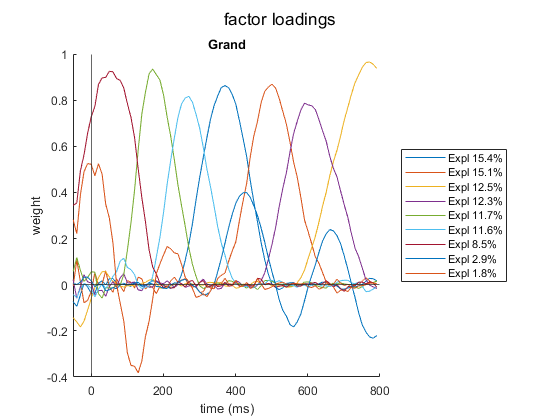

figure, sgtitle('factor loadings'), ax = zeros(1,n.group);
for i_g = 1:n.group
    ax(i_g) = subplot(n.group,1,i_g); hold on
    plot(P.t.plot,EEG(i_g).pca.FacPat), ylabel('weight') % .*EEG(i_g).pca.facVar
    % add legend
    lgnd = num2cell(EEG(i_g).pca.facVar*100); 
    lgnd = cellfun(@(x) sprintf('Expl %.1f%%',x),lgnd,'UniformOutput',false);
    xline(0,'DisplayName',''), yline(0,'DisplayName',''), title(EEG(i_g).group)
    legend(lgnd,'Location','eastoutside')
end
xlabel('time (ms)'), linkaxes(ax), xlim(P.t.win)

### TODO: score topoplots

### reconstructed components

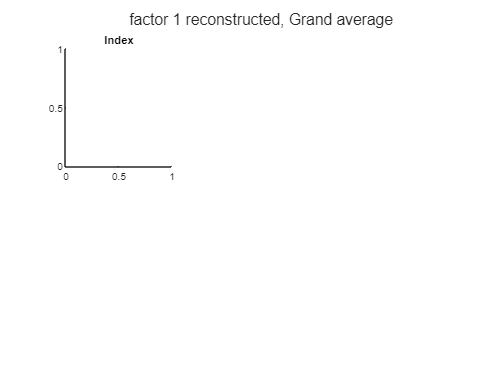

Unrecognized function or variable 'chanlocs'.

for i_g = 1:n.group
    for i_f = 1:EEG(i_g).pca.numFacs
        facName = ['r_temp' int2str(i_f)]; comp = EEG(i_g).(facName);
        figure; f = tiledlayout(2,n.cond); 
        title(f, ['factor ' int2str(i_f) ' reconstructed, ' EEG(i_g).group ' average'])
        % plot topography
        comp_s = squeeze( mean( mean(comp,3), 1 ) );
        for i_c = 1:n.cond
            nexttile([1 1]), title(task.conds{i_c})
            topoplot(comp_s(:,i_c),chanlocs,'verbose','off');
        end
        % plot timecourse
        nexttile([1 3]), hold on, title('timecourse')
        comp_t = squeeze(mean(comp(:,P.chan.plot_i,:,:),1));
        plot(P.t.plot,comp_t), xlabel('time (ms)'), xlim(P.t.win)
        legend(task.conds)
    end
end

### suppression (from factor scores)

% sort factor scores by group and factor
scores = cell(n.group,nF);
for i_g = 1:length(group)
    grp_scores = cat(4,DATA(group(i_g).ids).factor_scores);
    grp_scores = permute(grp_scores,[4 1 2 3]);
    for i_f = 1:nF
        scores{i_g,i_f} = squeeze(grp_scores(:,:,:,i_f));
    end
    clear grp_scores
end

for i_f = 1:nF
    figure, sgtitle(['Suppression: Factor ' int2str(i_f)])
    for i_g = 1:length(group)
        grsc = squeeze(scores{i_g,i_f}(:,P.chan.plot_i,:));
        suppression{i_g} = (grsc(:,1)+grsc(:,2)-grsc(:,3))./(grsc(:,1)+grsc(:,2));
    end
    plotSpread(suppression,'showMM',3)
    yline([0 1],'--'), ylim([-3 3]), xticklabels({group.name})
end

### individual reconstructed erps

% select factors to use for reconstruction
fac_ind = [2 6 7];
rc_erp  = zeros(EEG.n,P.chan.n,n.rsamp,n.cond);
% sum selected factors
for i_f = 1:length(fac_ind)
    rc_erp = rc_erp + EEG.(['r_temp' int2str(fac_ind(i_f))]);
end
% plot grand average
tiledlayout(3,3); nexttile([1 3]); hold on; title('grand average')
plot( P.t.plot,squeeze(mean(rc_erp(:,P.chan.plot_i,:,:),1)) )
xlim(P.t.win), xline(0,'--'), yline(0,'--')
% plot 6 random individuals
% r = randsample(1:31,6); ft = zeros(1,6);
for i_r = r
    nexttile([1 1]); ft(i_r) = gca; hold on
    title([int2str(DATA(i_r).id) ', ' group(DATA(i_r).group).name])
    plot( P.t.plot,squeeze( rc_erp(i_r,P.chan.pca==52,:,:) ) )
    xlim(P.t.win), xline(0,'--'), yline(0,'--')
end
linkaxes(ft)

### individual score topography

s_id = 29; i_f = 6; figure, tiledlayout(1,3)
for i_c = 1:n.cond
    nexttile; hold on; topoplot(EEG.pca.FacScrPerm(s_id,:,i_c,i_f),chanlocs); 
    colorbar(gca), caxis([-2 2]), title(task.conds{i_c})
end

### factor scores by group

if P.plot_facScr
    % plot factor scores by factor
    for i_f = 1:nF
        figure, sgtitle(['Standardized Factor ' int2str(i_f) ' scores'])
        ax = zeros(1,length(group));
        for i_g = 1:length(group)
            ax(i_g) = subplot(1,length(group),i_g); hold on
            % to do: plot sum/avg across all channels?
            grp_scores = squeeze(scores{i_g,i_f}(:,P.chan.plot_i,:));
            plotSpread(grp_scores,'showMM',3), clear grp_scores
            title(group(i_g).name), xticklabels(task.conds)
        end
        linkaxes(ax)
    end
end